# Lifting Surface Geometry Plots

clear
clc

## Load Geometry

load liftSurfGeom.mat
load wingCover.mat
load tail.mat

## Wing Plot

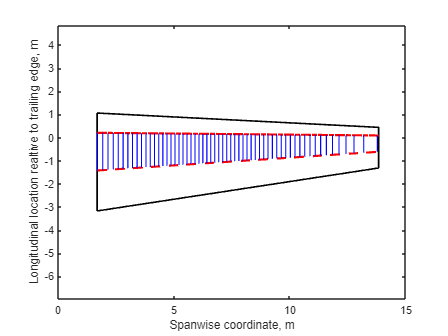

% Plot wing geometry
figure()
plot(wing.coords(:,1), wing.coords(:,2), 'LineWidth', 1.5, 'Color', 'black', 'DisplayName',...
    'Wing perimeter')
hold on
plot(wing.fsparCoords(:,1), wing.fsparCoords(:,2), '-.', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Front spar')
plot(wing.rsparCoords(:,1), wing.rsparCoords(:,2), '--', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Rear spar')

for i = 1:length(rib.distL)
    x = wing.TEfus + [rib.distL(1,i), rib.distL(1,i)];
    y = chordLocal(wing, rib.distL(1,i))*[0.25-wing.rspar, 0.25-wing.fspar];
    plot(x, y, '-', 'LineWidth', 1, 'Color', 'blue')
end

hold off
xlabel('Spanwise coordinate, m')
ylabel('Longitudinal location realtive to trailing edge, m')
xlim([0, 15])
ylim([-1, 5])
axis equal

% legend('Location','northeast')

## Horizontal Tail Plot

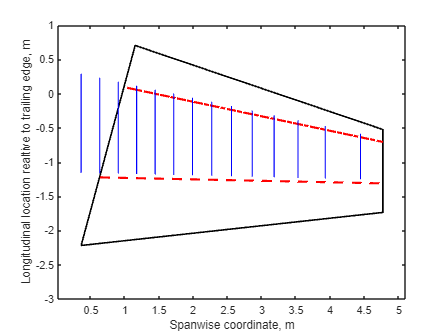

% Plot HT geometry
figure()
plot(HT.coords(:,1), HT.coords(:,2), 'LineWidth', 1.5, 'Color', 'black', 'DisplayName',...
    'Horizontal tail perimeter')
hold on
plot(HT.fsparCoords(:,1), HT.fsparCoords(:,2), '-.', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Front spar')
plot(HT.rsparCoords(:,1), HT.rsparCoords(:,2), '--', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Rear spar')
for i = 1:length(HTrib.distL)
    x = HT.TEfus + [HTrib.distL(1,i), HTrib.distL(1,i)];
    y = chordLocal(HT, HTrib.distL(1,i))*[0.25-HT.rspar, 0.25-HT.fspar] - HTrib.distL(1,i)*tand(HT.sweep);
    plot(x, y, '-', 'LineWidth', 1, 'Color', 'blue')
end
hold off
xlabel('Spanwise coordinate, m')
ylabel('Longitudinal location realtive to trailing edge, m')
xlim([0, 5])
ylim([-3, 1])
axis equal

% legend('Location','northeast')

## Vertical Tail Plot

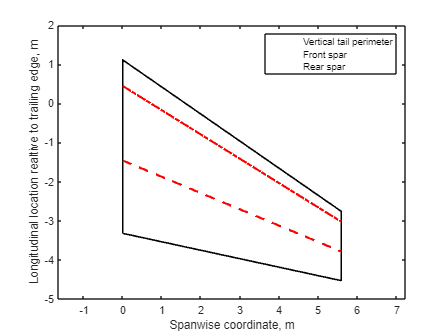

% Plot VT geometry
figure()
plot(VT.coords(:,1), VT.coords(:,2), 'LineWidth', 1.5, 'Color', 'black', 'DisplayName',...
    'Vertical tail perimeter')
hold on
plot(VT.fsparCoords(:,1), VT.fsparCoords(:,2), '-.', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Front spar')
plot(VT.rsparCoords(:,1), VT.rsparCoords(:,2), '--', 'LineWidth', 2, 'Color', 'red', 'DisplayName',...
    'Rear spar')
hold off
xlabel('Spanwise coordinate, m')
ylabel('Longitudinal location realtive to trailing edge, m')
xlim([0, 6])
ylim([-5, 2])
axis equal
legend('Location','northeast')